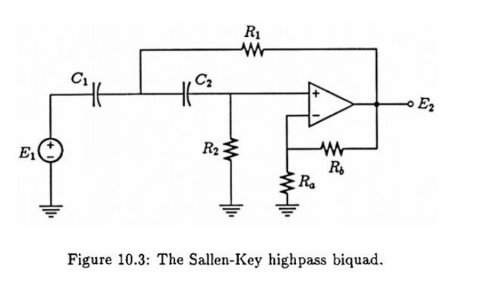

KCL:  $i_f=i_1+i_2
$

Let us assume of gain of 1 $\therefore$ $\frac{Rb}{Ra}$=1

syms R1 R2 E1 E2 Ex C1 C2 s

i_f=(E2-Ex)/R1

$$i\_f = \frac{E_{2}-\mathrm{Ex}}{R_{1}}$$

i_1=(Ex-E1)*s*C1

$$i\_1 = -C_{1}\,s\,\left(E_{1}-\mathrm{Ex}\right)$$

i_2=(Ex-E2)*s*C2

$$i\_2 = -C_{2}\,s\,\left(E_{2}-\mathrm{Ex}\right)$$

i_3=(E2/R2)

$$i\_3 = \frac{E_{2}}{R_{2}}$$

eq1=i_f==i_1+i_2

$$eq1 = \frac{E_{2}-\mathrm{Ex}}{R_{1}}=-C_{1}\,s\,\left(E_{1}-\mathrm{Ex}\right)-C_{2}\,s\,\left(E_{2}-\mathrm{Ex}\right)$$

eq2=i_2==i_3

$$eq2 = -C_{2}\,s\,\left(E_{2}-\mathrm{Ex}\right)=\frac{E_{2}}{R_{2}}$$

sol=solve(eq1,eq2,E1,E2);
H=sol.E2/sol.E1

$$H = \frac{C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}}{C_{1}\,R_{1}\,s+C_{2}\,R_{1}\,s+C_{1}\,C_{2}\,R_{1}\,R_{2}\,s^{2}+1}$$

Transfer Function 


$$$\frac{C_1 \,C_2 \,R_1 \,R_2 \,s^2 }{C_1 \,R_1 \,s+C_2 \,R_1 \,s+C_1 \,C_2 \,R_1 \,R_2 \,s^2 +1}$$$


To obtain a bode plot let us assume $\omega =1$

H=subs(H,[C1,C2,R1,R2],[1,1,1,1])

$$H = \frac{s^{2}}{s^{2}+2\,s+1}$$

num=[1,0,0];
den=[1 2 1];
sys=tf(num,den);
sys


sys =
 
       s^2
  -------------
  s^2 + 2 s + 1
 
Continuous-time transfer function.
Model Properties


%bode plot

[mag, phase, omega]=bode(sys)

mag = mag(:,:,1) =

   9.9990e-05


mag(:,:,2) =

   3.9984e-04


mag(:,:,3) =

   5.4669e-04


mag(:,:,4) =

   7.4743e-04


mag(:,:,5) =

    0.0010


mag(:,:,6) =

    0.0014


mag(:,:,7) =

    0.0019


mag(:,:,8) =

    0.0026


mag(:,:,9) =

    0.0036


mag(:,:,10) =

    0.0049


mag(:,:,11) =

    0.0066


mag(:,:,12) =

    0.0091


mag(:,:,13) =

    0.0099


mag(:,:,14) =

    0.0124


mag(:,:,15) =

    0.0168


mag(:,:,16) =

    0.0229


mag(:,:,17) =

    0.0310


mag(:,:,18) =

    0.0419


mag(:,:,19) =

    0.0564


mag(:,:,20) =

    0.0756


mag(:,:,21) =

    0.1006


mag(:,:,22) =

    0.1326


mag(:,:,23) =

    0.1730


mag(:,:,24) =

    0.2224


mag(:,:,25) =

    0.2811


mag(:,:,26) =

    0.3484


mag(:,:,27) =

    0.4224


mag(:,:,28) =

    0.5000


mag(:,:,29) =

    0.5776


mag(:,:,30) =

    0.6516


mag(:,:,31) =

    0.7189


mag(:,:,32) =

    0.7776


mag(:,:,33) =

    0.8270


mag(:,:,34) =

    0.8674


mag(:,:,35) =

    0.8994


mag(:,:,36)

phase = phase(:,:,1) =

  178.8541


phase(:,:,2) =

  177.7085


phase(:,:,3) =

  177.3204


phase(:,:,4) =

  176.8668


phase(:,:,5) =

  176.3364


phase(:,:,6) =

  175.7163


phase(:,:,7) =

  174.9916


phase(:,:,8) =

  174.1446


phase(:,:,9) =

  173.1549


phase(:,:,10) =

  171.9990


phase(:,:,11) =

  170.6493


phase(:,:,12) =

  169.0742


phase(:,:,13) =

  168.5788


phase(:,:,14) =

  167.2377


phase(:,:,15) =

  165.0985


phase(:,:,16) =

  162.6102


phase(:,:,17) =

  159.7214


phase(:,:,18) =

  156.3762


phase(:,:,19) =

  152.5159


phase(:,:,20) =

  148.0815


phase(:,:,21) =

  143.0184


phase(:,:,22) =

  137.2827


phase(:,:,23) =

  130.8503


phase(:,:,24) =

  123.7272


phase(:,:,25) =

  115.9603


phase(:,:,26) =

  107.6456


phase(:,:,27) =

   98.9293


phase(:,:,28) =

    90


phase(:,:,29) =

   81.0707


phase(:,:,30) =

   72.3544


phase(:,:,31) =

   64.0397


phase(:,:,32) =

   56.2728


phase(:,:,33) =

   49.1497


phase(:,:,34) =

omega =     0.0100
    0.0200
    0.0234
    0.0273
    0.0320
    0.0374
    0.0437
    0.0511
    0.0598
    0.0699


Error using semilogx
Data cannot have more than 2 dimensions.